# Savitzky-Golay Filtering

A program which is developed based on Savitzky-Golay approach for smoothing rate-normalized pressure (RNP) data.

Author: Munthe, Felix A.

Created on Monday, 30 October 2023

## Import Data

### True RNP Data

clear; clc; clf;
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
true_RNP = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\true_RNP.txt", opts)

true_RNP = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    2.6089e+06
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    1.7054e+07
     35.645    2.3347e+07
      66.06    3.1893e+07
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.3193e+07
     380.99     8.103e+07


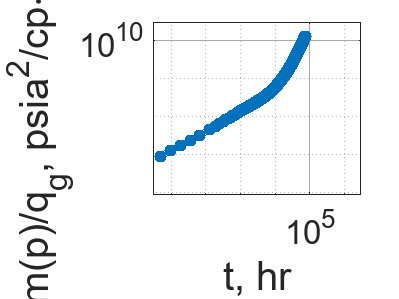


% Plot
loglog(true_RNP.t, true_RNP.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("True RNP Data", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

### Noisy RNP Data Set 189

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["t", "RNP"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
noisy_RNP_189 = readtable("C:\Users\ASUS\Documents\Kuliah\2. Master's Texas A&M University\Publications\Conference Paper\Smoothing Paper\Smoothing Simulator\Noisy RNP Model\All\25%\noisy_data_9.txt", opts)

noisy_RNP_189 = 1150×2 table
       t          RNP    
    _______    __________

       0.25    1.3616e+06
    0.33041    1.9565e+06
     0.4862    1.1448e+08
    0.79777    3.4782e+06
     1.4209    4.6953e+06
     2.6672    6.4232e+06
     5.0773    8.8236e+06
     9.8974    1.2258e+07
     19.198    3.1929e+07
     35.645    2.3347e+07
      66.06    2.9516e+08
     124.99    4.3906e+07
     188.99    5.4925e+07
     252.99    6.4572e+07
     316.99    7.4948e+07
     380.99     8.103e+07


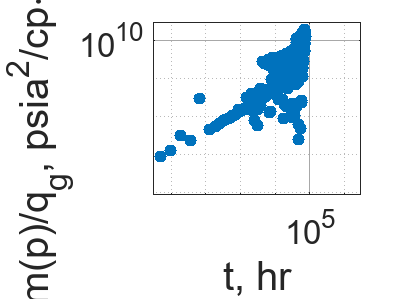


% Plot
loglog(noisy_RNP_189.t, noisy_RNP_189.RNP, ".", "MarkerSize", 25,"Color", "#0072BD");
% title("Noisy RNP Data Set 189", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold off;

## Smoothing

### Noisy RNP Data 189

logRNP_189 = log(noisy_RNP_189.RNP);

#### Window: 3

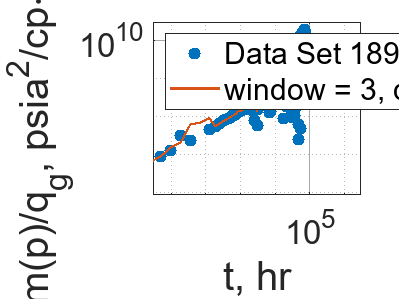

% Plot
loglog(noisy_RNP_189.t, noisy_RNP_189.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 189");
% title("Noisy RNP Data Set 189", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_189_31 = smooth(logRNP_189, 3, "sgolay", 1);
smoothedRNP_189_31 = exp(smoothedLogRNP_189_31);
residual_189_31 = (true_RNP.RNP - smoothedRNP_189_31) ./ (0.3413 .* true_RNP.RNP);
sse_189_31 = sum(residual_189_31 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_31, "-", "LineWidth", 1.3, "DisplayName", "window = 3, degree = 1");
legend("Location", "northwest");
hold off;

### Window: 5

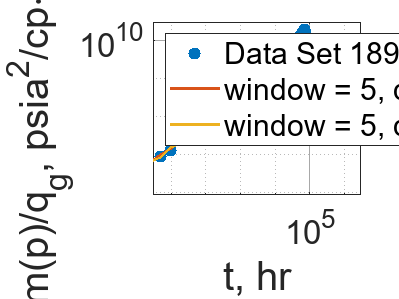

% Plot
loglog(noisy_RNP_189.t, noisy_RNP_189.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 189");
% title("Noisy RNP Data Set 189", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_189_51 = smooth(logRNP_189, 5, "sgolay", 1);
smoothedRNP_189_51 = exp(smoothedLogRNP_189_51);
residual_189_51 = (true_RNP.RNP - smoothedRNP_189_51) ./ (0.3413 .* true_RNP.RNP);
sse_189_51 = sum(residual_189_51 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_51, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_189_52 = smooth(logRNP_189, 5, "sgolay", 2);
smoothedRNP_189_52 = exp(smoothedLogRNP_189_52);
residual_189_52 = (true_RNP.RNP - smoothedRNP_189_52) ./ (0.3413 .* true_RNP.RNP);
sse_189_52 = sum(residual_189_52 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_52, "-", "LineWidth", 1.3, "DisplayName", "window = 5, degree = 2");
legend("Location", "northwest");
hold off;

#### Window: 7

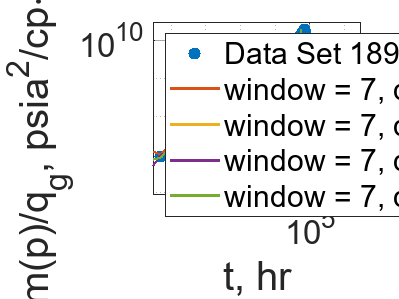

% Plot
loglog(noisy_RNP_189.t, noisy_RNP_189.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 189");
% title("Noisy RNP Data Set 189", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_189_71 = smooth(logRNP_189, 7, "sgolay", 1);
smoothedRNP_189_71 = exp(smoothedLogRNP_189_71);
residual_189_71 = (true_RNP.RNP - smoothedRNP_189_71) ./ (0.3413 .* true_RNP.RNP);
sse_189_71 = sum(residual_189_71 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_71, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_189_72 = smooth(logRNP_189, 7, "sgolay", 2);
smoothedRNP_189_72 = exp(smoothedLogRNP_189_72);
residual_189_72 = (true_RNP.RNP - smoothedRNP_189_72) ./ (0.3413 .* true_RNP.RNP);
sse_189_72 = sum(residual_189_72 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_72, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_189_73 = smooth(logRNP_189, 7, "sgolay", 3);
smoothedRNP_189_73 = exp(smoothedLogRNP_189_73);
residual_189_73 = (true_RNP.RNP - smoothedRNP_189_73) ./ (0.3413 .* true_RNP.RNP);
sse_189_73 = sum(residual_189_73 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_73, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_189_74 = smooth(logRNP_189, 7, "sgolay", 4);
smoothedRNP_189_74 = exp(smoothedLogRNP_189_74);
residual_189_74 = (true_RNP.RNP - smoothedRNP_189_74) ./ (0.3413 .* true_RNP.RNP);
sse_189_74 = sum(residual_189_74 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_74, "-", "LineWidth", 1.3, "DisplayName", "window = 7, degree = 4");
legend("Location", "northwest");
hold off;

#### Window: 9

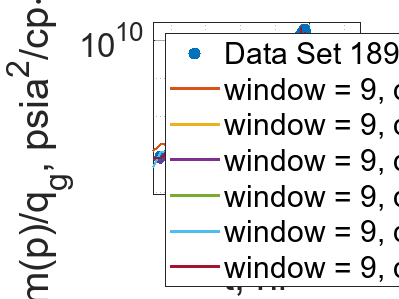

% Plot
loglog(noisy_RNP_189.t, noisy_RNP_189.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 189");
% title("Noisy RNP Data Set 189", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_189_91 = smooth(logRNP_189, 9, "sgolay", 1);
smoothedRNP_189_91 = exp(smoothedLogRNP_189_91);
residual_189_91 = (true_RNP.RNP - smoothedRNP_189_91) ./ (0.3413 .* true_RNP.RNP);
sse_189_91 = sum(residual_189_91 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_91, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_189_92 = smooth(logRNP_189, 9, "sgolay", 2);
smoothedRNP_189_92 = exp(smoothedLogRNP_189_92);
residual_189_92 = (true_RNP.RNP - smoothedRNP_189_92) ./ (0.3413 .* true_RNP.RNP);
sse_189_92 = sum(residual_189_92 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_92, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_189_93 = smooth(logRNP_189, 9, "sgolay", 3);
smoothedRNP_189_93 = exp(smoothedLogRNP_189_93);
residual_189_93 = (true_RNP.RNP - smoothedRNP_189_93) ./ (0.3413 .* true_RNP.RNP);
sse_189_93 = sum(residual_189_93 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_93, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_189_94 = smooth(logRNP_189, 9, "sgolay", 4);
smoothedRNP_189_94 = exp(smoothedLogRNP_189_94);
residual_189_94 = (true_RNP.RNP - smoothedRNP_189_94) ./ (0.3413 .* true_RNP.RNP);
sse_189_94 = sum(residual_189_94 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_94, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_189_95 = smooth(logRNP_189, 9, "sgolay", 5);
smoothedRNP_189_95 = exp(smoothedLogRNP_189_95);
residual_189_95 = (true_RNP.RNP - smoothedRNP_189_95) ./ (0.3413 .* true_RNP.RNP);
sse_189_95 = sum(residual_189_95 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_95, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_189_96 = smooth(logRNP_189, 9, "sgolay", 6);
smoothedRNP_189_96 = exp(smoothedLogRNP_189_96);
residual_189_96 = (true_RNP.RNP - smoothedRNP_189_96) ./ (0.3413 .* true_RNP.RNP);
sse_189_96 = sum(residual_189_96 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_96, "-", "LineWidth", 1.3, "DisplayName", "window = 9, degree = 6");
legend("Location", "northwest");
hold off;

#### Window: 11

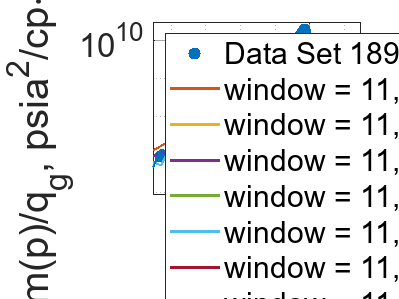

% Plot
loglog(noisy_RNP_189.t, noisy_RNP_189.RNP, ".", "MarkerSize", 25,"Color", "#0072BD", "DisplayName", "Data Set 189");
% title("Noisy RNP Data Set 189", "FontSize", 24);
set(gca, "FontSize", 20);
xlabel("t, hr", "FontSize", 24);
ylabel("\Deltam(p)/q_{g}, psia^{2}/cp\cdotd/Mscf", "FontSize", 24);
xlim([3 3000000]);
ylim([900000 30000000000]);
set(gca, "GridAlpha", 0.4);
set(gca, "MinorGridAlpha", 0.3);
grid on;
hold on;

% Degree = 1
smoothedLogRNP_189_111 = smooth(logRNP_189, 11, "sgolay", 1);
smoothedRNP_189_111 = exp(smoothedLogRNP_189_111);
residual_189_111 = (true_RNP.RNP - smoothedRNP_189_111) ./ (0.3413 .* true_RNP.RNP);
sse_189_111 = sum(residual_189_111 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_111, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 1");
hold on;

% Degree = 2
smoothedLogRNP_189_112 = smooth(logRNP_189, 11, "sgolay", 2);
smoothedRNP_189_112 = exp(smoothedLogRNP_189_112);
residual_189_112 = (true_RNP.RNP - smoothedRNP_189_112) ./ (0.3413 .* true_RNP.RNP);
sse_189_112 = sum(residual_189_112 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_112, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 2");
hold on;

% Degree = 3
smoothedLogRNP_189_113 = smooth(logRNP_189, 11, "sgolay", 3);
smoothedRNP_189_113 = exp(smoothedLogRNP_189_113);
residual_189_113 = (true_RNP.RNP - smoothedRNP_189_113) ./ (0.3413 .* true_RNP.RNP);
sse_189_113 = sum(residual_189_113 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_113, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 3");
hold on;

% Degree = 4
smoothedLogRNP_189_114 = smooth(logRNP_189, 11, "sgolay", 4);
smoothedRNP_189_114 = exp(smoothedLogRNP_189_114);
residual_189_114 = (true_RNP.RNP - smoothedRNP_189_114) ./ (0.3413 .* true_RNP.RNP);
sse_189_114 = sum(residual_189_114 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_114, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 4");
hold on;

% Degree = 5
smoothedLogRNP_189_115 = smooth(logRNP_189, 11, "sgolay", 5);
smoothedRNP_189_115 = exp(smoothedLogRNP_189_115);
residual_189_115 = (true_RNP.RNP - smoothedRNP_189_115) ./ (0.3413 .* true_RNP.RNP);
sse_189_115 = sum(residual_189_115 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_115, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 5");
hold on;

% Degree = 6
smoothedLogRNP_189_116 = smooth(logRNP_189, 11, "sgolay", 6);
smoothedRNP_189_116 = exp(smoothedLogRNP_189_116);
residual_189_116 = (true_RNP.RNP - smoothedRNP_189_116) ./ (0.3413 .* true_RNP.RNP);
sse_189_116 = sum(residual_189_116 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_116, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 6");
hold on;

% Degree = 7
smoothedLogRNP_189_117 = smooth(logRNP_189, 11, "sgolay", 7);
smoothedRNP_189_117 = exp(smoothedLogRNP_189_117);
residual_189_117 = (true_RNP.RNP - smoothedRNP_189_117) ./ (0.3413 .* true_RNP.RNP);
sse_189_117 = sum(residual_189_117 .^ 2);
loglog(noisy_RNP_189.t, smoothedRNP_189_117, "-", "LineWidth", 1.3, "DisplayName", "window = 11, degree = 7");
legend("Location", "northwest");
hold off;